# Ejercicios raíces

## Tanque esférico de radio R

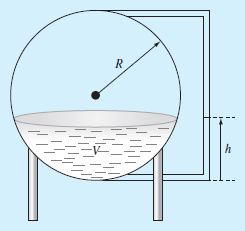


$$V=\pi h^2 \left(\frac{3R-h}{3}\right)$$


Queremos encontrar h tal $V=V_d$ deseada

Vd = 30;
R = 3;
hu=3;
v=@(h)pi.*(h.^2)*((3.*R-h)./3)-Vd;
[h i]=nr(v,hu)

h = 2.0269

i = 5

## Bungee jumper 

Determina la masa máxima que puede tener un saltador si, por motivos de seguridad, la velocidad no puede exceder de 33m/s a los 4s. 


$$v=\sqrt{g\frac{m}{c_d }\;}$$

$$\mathrm{tanh}\left(\sqrt{g\frac{c_d }{m}}\;t\right)$$


g = 9.81;
cd = 0.25;
vM = 33;
t = 4;
m0=80;
v=@(m)sqrt(g*m/cd)*tanh(sqrt(g*cd/m)*t)-vM;
[m i]=nr(v,m0)

m = 66.6000

i = 6

## Principio de Arquímedes y una esfera de radio r

De acuerdo con el principio de Arquímedes, la **fuerza de flotación** es igual al **peso del fluido desplazado** por la porción sumergida de un objeto. Para la esfera de corcho ilustrada en la siguiente figura, usa el método de bisección para determinar la altura h de la porción que queda encima del agua. Utiliza los siguientes valores para tu cálculo: r = 1m, densidad de la esfera ρe = 200kg/m3 y densidad del agua ρa= 1000kg/m3. Observa que el volumen de la porción de la esfera por encima del agua se puede calcular mediante

 
$$V=\frac{\pi h^2 }{3}\left(3r-h\right)$$


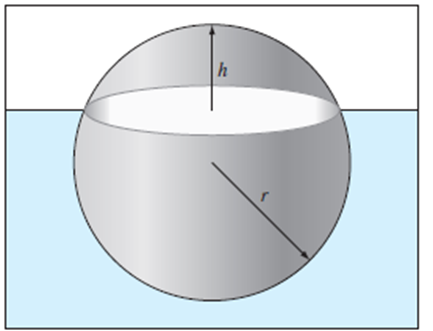

Para estar en equilibrio, la fuerza de flotación (que depende de h) debe ser igual al peso total de la esfera. Recuerda que F=mg y m=ρV. Por lo tanto, F = ρVg.

¿Peso de la esfera? ¿Volumen sumergido (desplazado)? ¿Fuerza de flotación? En equilibrio la fuerza total es cero. 

r=1;
pa=1000;
pe=200;
F= @(h) pa.*((pi.*h^3)./3).*(3.*r-h).*g-pi.*800./3;
xl=0;
xu=1;
[h i]=BiseccionMetodo(F,xl,xu)

h = 0.3119

i = 54

function [xr,i]=nr(f, xu)
%Hallar la raíz de la funcion f entre xl y xu. Empleando el método de
%Newton Rapsohd

     MAX = 52;
     tolerancia = eps;
     i = 0;
     condicion= true;
     fx=sym(f);
     dfs= diff(fx);
     df=matlabFunction(dfs);
     
     while condicion
         xr= xu-(f(xu)/df(xu));
         i=i+1;
         condicion= abs((xr-xu)/xr) > tolerancia  && i < MAX;
         xu=xr;
         
     end
     
end
function [xr,i]=BiseccionMetodo(f,xl,xu)
%Hallar la raíz de la funcion f entre xl y xu. Empleando el método de
%bisección

% f(xl) y f(xu) tienen que tener signos diferentes, sino la función no va a
    % poder trabajar.
     if sign(f(xl))*sign(f(xu)) > 0
        error('f(xl)f(xu) < 0 no se satisface')
     end

     MAX = 55;
     tolerancia = eps;
     xr = (xl+xu)/2;
     fx = f(xr);
     i = 0;

     while abs((xu-xl)/xu) > tolerancia && fx~=0 && i < MAX
         if sign(fx) ~= sign(f(xl))
             xu = xr;
         else
             xl = xr;
         end
         xr=(xl+xu)/2;
         fx=f(xr);
         i=i+1;
     end
end